# **A neuroimaging biomarker for sustained experimental and clinical pain**

## **Chapter 2. Applying ToPS onto multiple participants' fMRI data**

### Introduction

Welcome! In this tutorial, we will introduce you how to apply Tonic Pain Signature (ToPS) onto multiple participant's fMRI data and re-generate some of the main figures of our reference paper (Lee et al., 2020).

#### Contents

- Basic settings

- Visualize Tonic Pain Signature (ToPS): Extended Data Fig. 7

- Use ToPS for predicting tonic pain intensity: Fig. 2

- Use ToPS for predicting overall level of clinical back pain: Fig. 3

- Use ToPS for discriminating patients with back pain from healthy control: Fig. 3

#### Requirements

- **ToPS**: The model will be shared via a Material Transfer Agreement (only for the scientific research purpose). After downloading the model file ("ToPS_weight.mat"), please place it within the "tops/model/" folder (path: "tops/model/ToPS_weight.mat").

- **Data**: The tutorial data are available at the following [figshare](https://figshare.com/articles/dataset/data_zip/13082519) page. After downloading the compressed data file ("data.zip"), uncompress it and place the "data" folder within the "tops" folder (path: "tops/data").

#### Reference

- Jae-Joong Lee, Hong Ji Kim, Marta Ceko, Bo-yong Park, Soo Ahn Lee, Hyunjin Park, Mathieu Roy, Seong-Gi Kim, Tor D. Wager*, Choong-Wan Woo*, A neuroimaging biomarker for sustained experimental and clinical pain, 2020, *Nature Medicine* (*co-corresponding authors)

### 1. Basic settings

First. we will set path to this project and add functions as the previous tutorial code. Please note  that most of these functions were copied (and edited a bit) from [CanlabCore](https://github.com/canlab/CanlabCore) and [cocoanCORE](https://github.com/cocoanlab/cocoanCORE).

basedir = '~/github/cocoanlab/tops'; % Check this path!
addpath(genpath(fullfile(basedir, 'functions')));

Then, let's load the ToPS.

load(fullfile(basedir, 'model/ToPS_weight.mat'), 'ToPS_w');

Also, functional connectivity data and pain ratings of multiple datasets (Studies 3, 4, 5).

load(fullfile(basedir, 'data/whole_participants/FC_and_pain/merged_FC_and_pain_rating.mat'), 'Study*');

Finally, a structure object containing useful information about 279-region Brainnetome atlas.

load(fullfile(basedir, 'data/atlas/cluster_Fan_Net_r279.mat'));

### 2. Visualize Tonic Pain Signature (ToPS): Extended Data Fig. 7

Before testing the ToPS, let's see overall patterns of predictive weights of the ToPS in a circos plot. ToPS was based on 279-region Brainnetome parcellation, so there are 38,781 connection-level weights to be displayed. We represent the sign of predictive weights as line color (red = positive, blue = negative), and the strength of predictive weights as line alpha and line width (high alpha and width = high strength).

Note: This section requires a large amount of memory for displaying figure. If you ran out of memory, please consider clearing all the output.

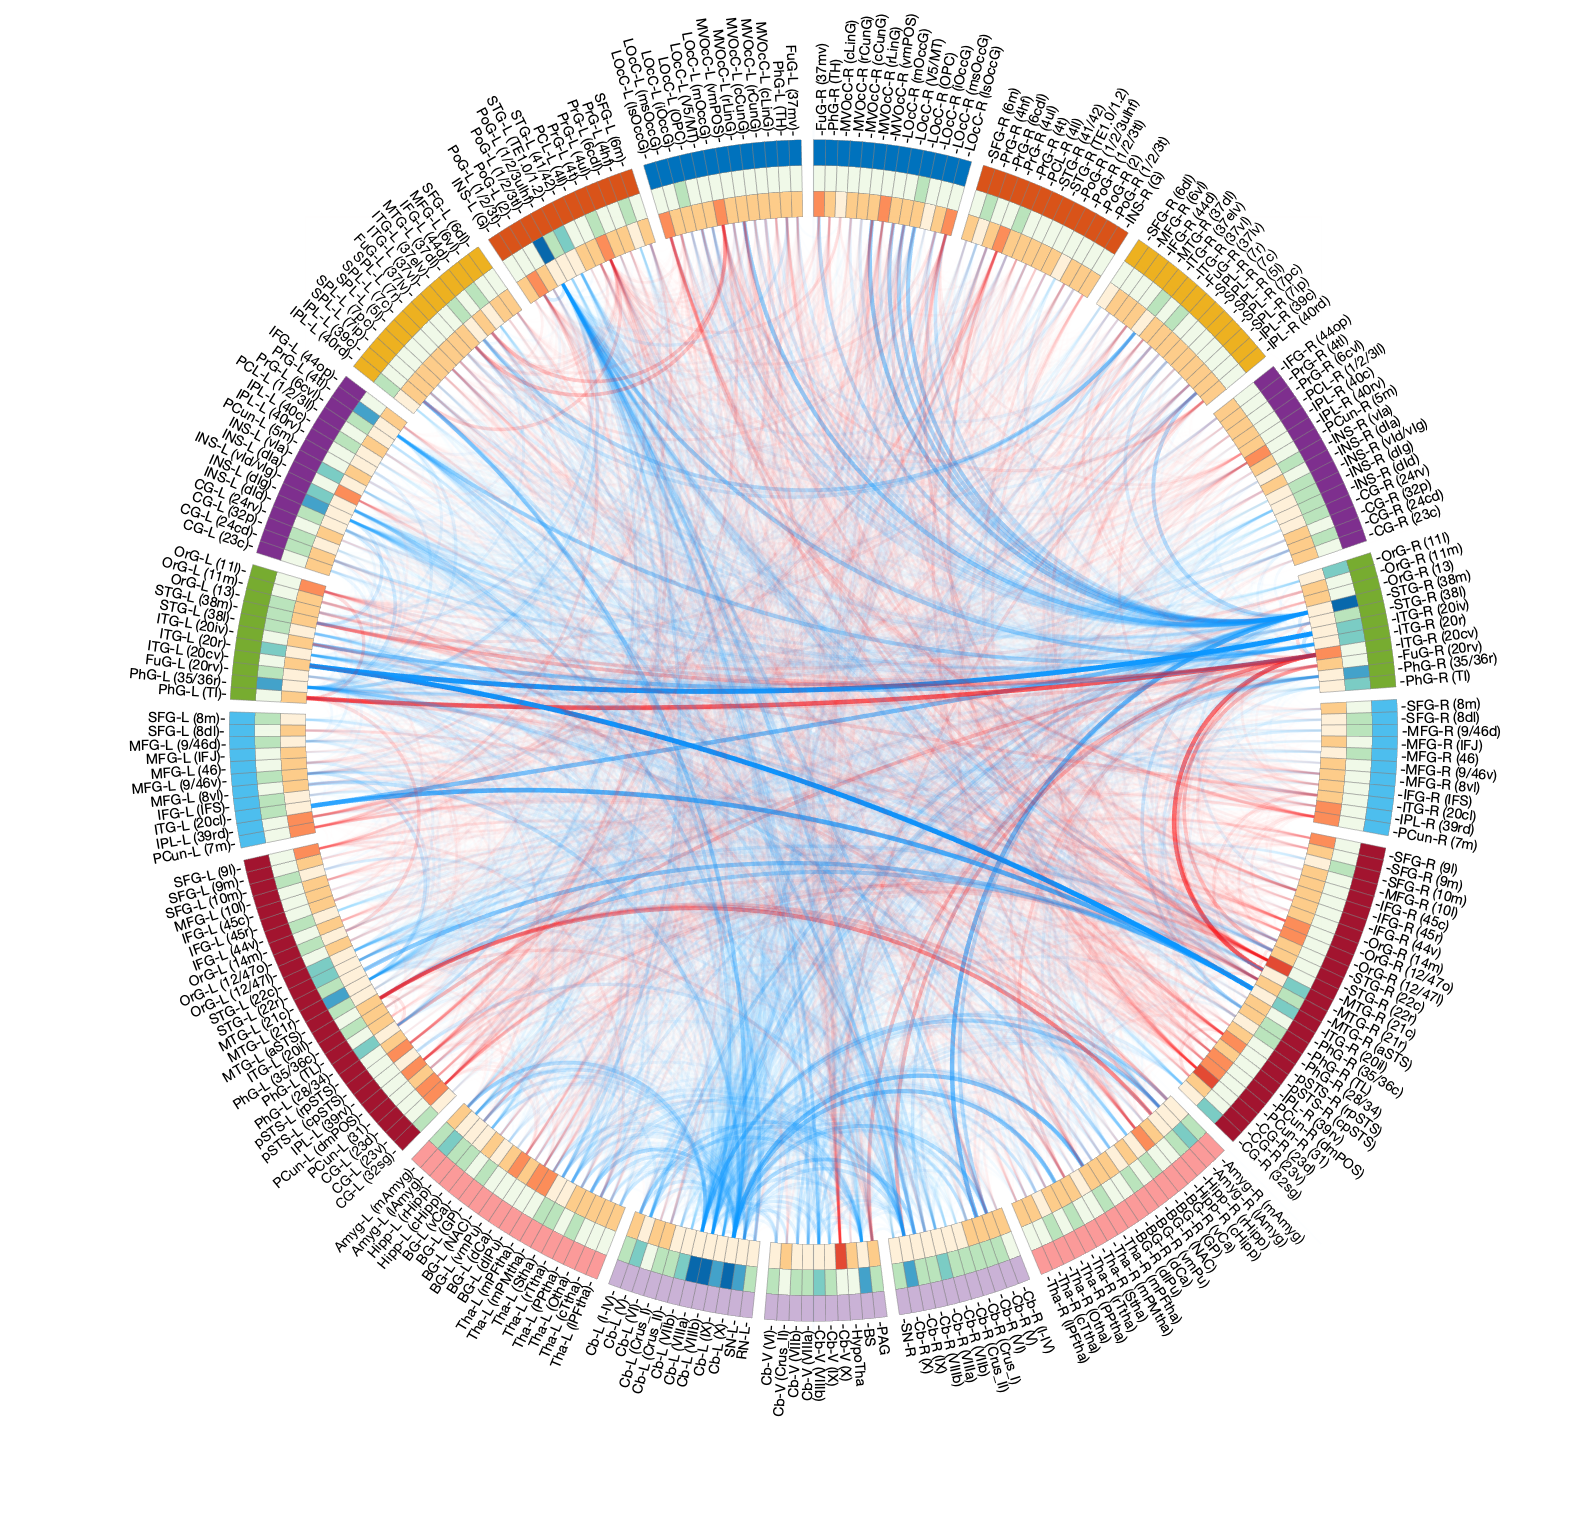

col_pos_deg = [0.9961    0.9412    0.8510
    0.9922    0.8000    0.5412
    0.9882    0.5529    0.3490
    0.8902    0.2902    0.2000
    0.7020         0         0];
col_neg_deg = [0.9412    0.9765    0.9098
    0.7294    0.8941    0.7373
    0.4824    0.8000    0.7686
    0.2627    0.6353    0.7922
    0.0314    0.4078    0.6745];

ToPS_w_recon = reformat_r_new(ToPS_w, 'reconstruct');
pos_deg = sum(ToPS_w_recon .* double(ToPS_w_recon>0));
neg_deg = -sum(ToPS_w_recon .* double(ToPS_w_recon<0));
norm_pos_deg = (pos_deg - min([pos_deg neg_deg])) ./ (max([pos_deg, neg_deg]) - min([pos_deg, neg_deg]));
norm_neg_deg = (neg_deg - min([pos_deg neg_deg])) ./ (max([pos_deg, neg_deg]) - min([pos_deg, neg_deg]));

figure;
set(gcf, 'visible', 'on');
circos_multilayer(ToPS_w_recon, ...
    'group', cluster_Fan_Net.dat(:,3), 'group_color', cluster_Fan_Net.nine_network_col, ...
    'add_layer', {'layer', norm_pos_deg, 'color', col_pos_deg, 'layer', norm_neg_deg, 'color', col_neg_deg}, ...
    'region_names', cluster_Fan_Net.names_short, 'region_names_size', 7, 'laterality', cluster_Fan_Net.dat(:,7), 'sep_pos_neg');
set(gca, 'xlim', [-1.2 1.2], 'ylim', [-1.2 1.2]);
set(gcf, 'position', [40    40   786   762]);

### 3. Use ToPS for predicting tonic pain intensity: Fig. 2

Next we will move on to applying to ToPS onto an independent tonic pain dataset, Study 3 (*n* = 48). Dynamic functional connectivity data are in "Study3" structure that was loaded before.

n_subj = numel(Study3.dfc_5bin_dat.CAPS);

for subj_i = 1:n_subj
    
    % 10-binned data
    Study3.ToPS_10bin.REST{subj_i} = sum(bsxfun(@times, Study3.dfc_10bin_dat.REST{subj_i}, ToPS_w), 1, 'omitnan')';
    Study3.ToPS_10bin.CAPS{subj_i} = sum(bsxfun(@times, Study3.dfc_10bin_dat.CAPS{subj_i}, ToPS_w), 1, 'omitnan')';
    Study3.ToPS_10bin.QUIN{subj_i} = sum(bsxfun(@times, Study3.dfc_10bin_dat.QUIN{subj_i}, ToPS_w), 1, 'omitnan')';
    Study3.ToPS_10bin.ODOR{subj_i} = sum(bsxfun(@times, Study3.dfc_10bin_dat.ODOR{subj_i}, ToPS_w), 1, 'omitnan')';
    
    % 5-binned data
    Study3.ToPS_5bin.REST{subj_i} = sum(bsxfun(@times, Study3.dfc_5bin_dat.REST{subj_i}, ToPS_w), 1, 'omitnan')';
    Study3.ToPS_5bin.CAPS{subj_i} = sum(bsxfun(@times, Study3.dfc_5bin_dat.CAPS{subj_i}, ToPS_w), 1, 'omitnan')';
    Study3.ToPS_5bin.QUIN{subj_i} = sum(bsxfun(@times, Study3.dfc_5bin_dat.QUIN{subj_i}, ToPS_w), 1, 'omitnan')';
    Study3.ToPS_5bin.ODOR{subj_i} = sum(bsxfun(@times, Study3.dfc_5bin_dat.ODOR{subj_i}, ToPS_w), 1, 'omitnan')';
    
    % 1-binned (time-averaged) data
    Study3.ToPS_avg.REST{subj_i} = sum(bsxfun(@times, Study3.dfc_avg_dat.REST{subj_i}, ToPS_w), 1, 'omitnan')';
    Study3.ToPS_avg.CAPS{subj_i} = sum(bsxfun(@times, Study3.dfc_avg_dat.CAPS{subj_i}, ToPS_w), 1, 'omitnan')';
    Study3.ToPS_avg.QUIN{subj_i} = sum(bsxfun(@times, Study3.dfc_avg_dat.QUIN{subj_i}, ToPS_w), 1, 'omitnan')';
    Study3.ToPS_avg.ODOR{subj_i} = sum(bsxfun(@times, Study3.dfc_avg_dat.ODOR{subj_i}, ToPS_w), 1, 'omitnan')';
    
end

Based on the signature scores, let's display Y-Yfit plot (i.e., actual-versus-predicted plot). Here we use 5-binned data.

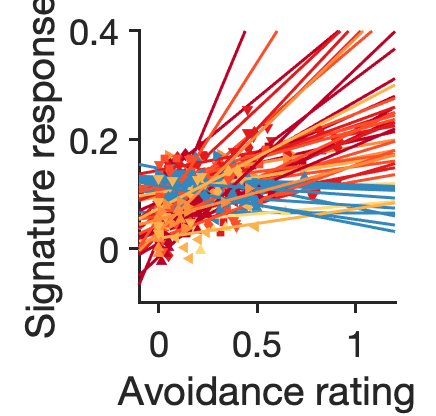

%% Study 3: Y-Yfit plot (Fig. 2c)
actual_rating = [cat(2, Study3.pain_5bin_dat.CAPS{:}); cat(2, Study3.pain_5bin_dat.REST{:})];
signature_response = [cat(2, Study3.ToPS_5bin.CAPS{:}); cat(2, Study3.ToPS_5bin.REST{:})];

figure;
out = plot_y_yfit(actual_rating, signature_response, 'data_alpha', 1, 'line_alpha', 0.7, 'dotsize', 25, 'xlim', [-0.1 1.2], 'ylim', [-0.1 0.4]);
xlabel('Avoidance rating', 'fontsize', 18); ylabel('Signature response', 'fontsize', 18);

fprintf('mean prediction-outcome correlation r: %.2f.\n', mean(out.r));

mean prediction-outcome correlation r: 0.51.


Also, let's see the temporal trend of actual pain ratings and signature scores. Here ,10-binned data are used for display.

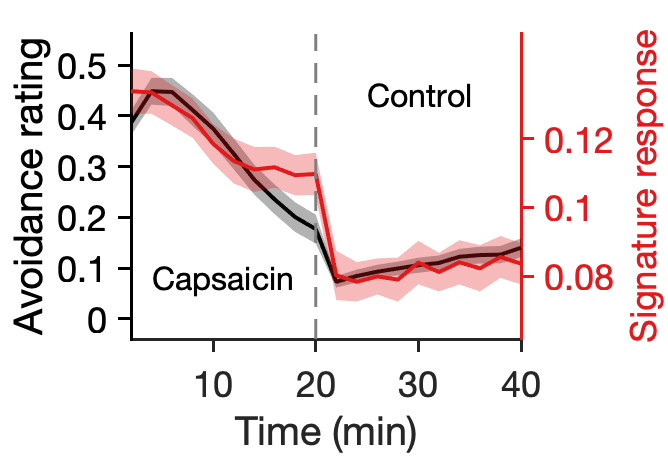

%% Study 3: Trace plot (Fig. 2c)
actual_rating = [cat(2, Study3.pain_10bin_dat.CAPS{:}); cat(2, Study3.pain_10bin_dat.REST{:})];
signature_response = [cat(2, Study3.ToPS_10bin.CAPS{:}); cat(2, Study3.ToPS_10bin.REST{:})];

figure;
trace_plot_overlap(actual_rating', signature_response');
xlabel('Time (min)', 'fontsize', 18);
set(gca, 'xtick', 0:5:20, 'xticklabel', 0:10:40, 'xlim', [1 20]);
yyaxis left; set(gca, 'ytick', [0:0.1:0.5]); ylabel('Avoidance rating', 'fontsize', 18);
yyaxis right; set(gca, 'ytick', [0.08:0.02:0.12]); ylabel('Signature response', 'fontsize', 18);
ylim_val = get(gca, 'ylim');
line([10 10], ylim_val, 'linewidth', 1.5, 'color', [.5 .5 .5], 'linestyle', '--');
text([2; 12.5], [ylim_val(1) + diff(ylim_val)*0.2; ylim_val(2) - diff(ylim_val)*0.2], {'Capsaicin', 'Control'}, 'Fontsize', 16);

In addition, we will examine whether the ToPS has specificity to tonic pain, and not to the other tonic but non-painful aversive states, including bitter taste (induced by quinine) and aversve odor (induced by fermented skate).

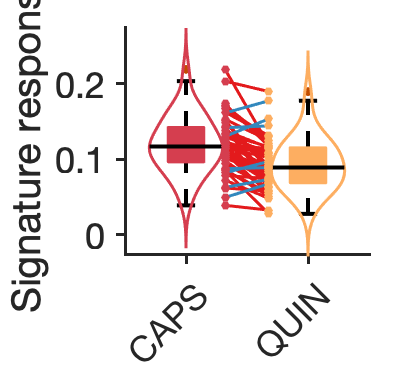

%% Study 3: Specificity plot: CAPS vs. QUIN, and CAPS vs. ODOR (Fig. 2d)
signature_response1 = cat(2, Study3.ToPS_avg.CAPS{:})';
signature_response2 = cat(2, Study3.ToPS_avg.QUIN{:})';
signature_response3 = cat(2, Study3.ToPS_avg.ODOR{:})';

cols_spec = [0.8353    0.2431    0.3098
    0.9922    0.6824    0.3804
    0.8667    0.6824    0.9294];

figure;
out = plot_specificity_box(signature_response1, signature_response2, 'colors', cols_spec([1,2],:));
ylabel('Signature response', 'fontsize', 18); xticklabels({'CAPS', 'QUIN'}); xtickangle(45);

fprintf('Capsaicin vs. Bitter taste: classification accuracy = %d%%.\n', round(100*mean(signature_response1 > signature_response2)));

Capsaicin vs. Bitter taste: classification accuracy = 85%.


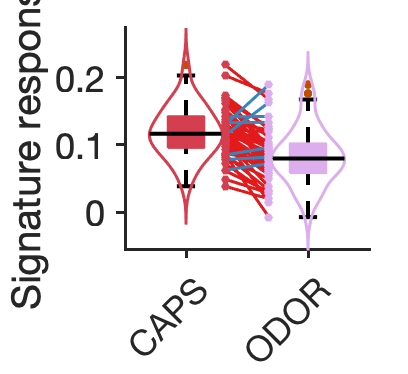

figure;
out = plot_specificity_box(signature_response1, signature_response3, 'colors', cols_spec([1,3],:));
ylabel('Signature response', 'fontsize', 18); xticklabels({'CAPS', 'ODOR'}); xtickangle(45);

fprintf('Capsaicin vs. Aversive odor: classification accuracy = %d%%.\n', round(100*mean(signature_response1 > signature_response2)));

Capsaicin vs. Aversive odor: classification accuracy = 85%.


### 4. Use ToPS for predicting overall level of clinical back pain: Fig. 3

Now we will examine the generalizability of the ToPS to patients with clinical back pain (Study 4, *n* = 95). Dynamic functional connectivity data are in "Study4" structure that was loaded before.

n_subj_SBP_SP = numel(Study4.dfc_avg_dat.SBP_SP); % SBP group, spontaneous pain rating condition
n_subj_SBP_REST = numel(Study4.dfc_avg_dat.SBP_REST); % SBP group, resting state condition
n_subj_CBP_SP = numel(Study4.dfc_avg_dat.CBP_SP); % CBP group, spontaneous pain rating condition
n_subj_CBP_REST = numel(Study4.dfc_avg_dat.CBP_REST); % CBP group, resting state condition

for subj_i = 1:n_subj_SBP_SP
    Study4.ToPS_avg.SBP_SP{subj_i} = sum(bsxfun(@times, Study4.dfc_avg_dat.SBP_SP{subj_i}, ToPS_w), 1, 'omitnan')';
end
for subj_i = 1:n_subj_SBP_REST
    Study4.ToPS_avg.SBP_REST{subj_i} = sum(bsxfun(@times, Study4.dfc_avg_dat.SBP_REST{subj_i}, ToPS_w), 1, 'omitnan')';
end
for subj_i = 1:n_subj_CBP_SP
    Study4.ToPS_avg.CBP_SP{subj_i} = sum(bsxfun(@times, Study4.dfc_avg_dat.CBP_SP{subj_i}, ToPS_w), 1, 'omitnan')';
end
for subj_i = 1:n_subj_CBP_REST
    Study4.ToPS_avg.CBP_REST{subj_i} = sum(bsxfun(@times, Study4.dfc_avg_dat.CBP_REST{subj_i}, ToPS_w), 1, 'omitnan')';
end

Based on the signature scores, let's display Y-Yfit plot (i.e., actual-versus-predicted plot).

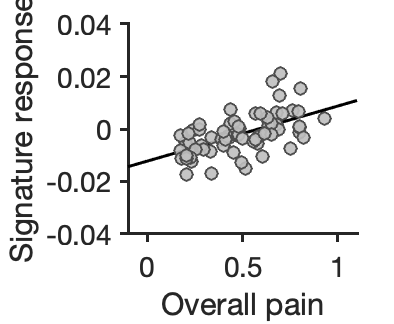

%% Study 4: Y-Yfit plot, SBP, spontaneous pain rating condition (Fig. 3a)
actual_rating = cat(2, Study4.pain_avg_dat.SBP_SP{:});
signature_response = cat(2, Study4.ToPS_avg.SBP_SP{:});

figure;
out = plot_y_yfit_simple(actual_rating, signature_response);
xlabel('Overall pain', 'fontsize', 18); ylabel('Signature response', 'fontsize', 18);

fprintf('mean prediction-outcome correlation r: %.2f.\n', mean(out.r));

mean prediction-outcome correlation r: 0.57.


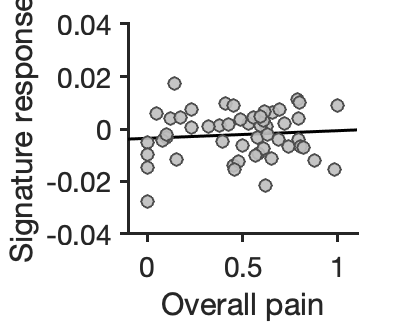

%% Study 4: Y-Yfit plot, SBP, resting state condition (Fig. 3a)
actual_rating = cat(2, Study4.pain_avg_dat.SBP_REST{:});
signature_response = cat(2, Study4.ToPS_avg.SBP_REST{:});

figure;
out = plot_y_yfit_simple(actual_rating, signature_response);
xlabel('Overall pain', 'fontsize', 18); ylabel('Signature response', 'fontsize', 18);

fprintf('mean prediction-outcome correlation r: %.2f.\n', mean(out.r));

mean prediction-outcome correlation r: 0.09.


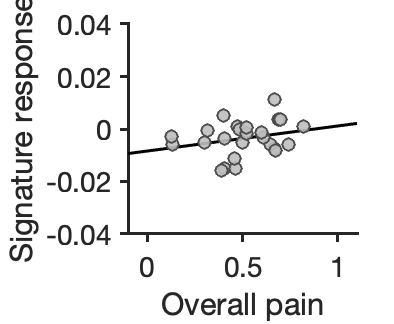

%% Study 4: Y-Yfit plot, CBP, spontaneous pain rating condition (Fig. 3b)
actual_rating = cat(2, Study4.pain_avg_dat.CBP_SP{:});
signature_response = cat(2, Study4.ToPS_avg.CBP_SP{:});

figure;
out = plot_y_yfit_simple(actual_rating, signature_response);
xlabel('Overall pain', 'fontsize', 18); ylabel('Signature response', 'fontsize', 18);

fprintf('mean prediction-outcome correlation r: %.2f.\n', mean(out.r));

mean prediction-outcome correlation r: 0.26.


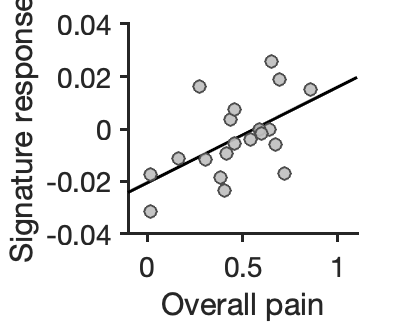

%% Study 4: Y-Yfit plot, CBP, resting state condition (Fig. 3b)
actual_rating = cat(2, Study4.pain_avg_dat.CBP_REST{:});
signature_response = cat(2, Study4.ToPS_avg.CBP_REST{:});

figure;
out = plot_y_yfit_simple(actual_rating, signature_response);
xlabel('Overall pain', 'fontsize', 18); ylabel('Signature response', 'fontsize', 18);

fprintf('mean prediction-outcome correlation r: %.2f.\n', mean(out.r));

mean prediction-outcome correlation r: 0.56.


### 5. Use ToPS for discriminating patients with back pain from healthy control: Fig. 3

Finally, we will test whether the ToPS can discriminate patients with clinical back pain from age-matched healthy control participants (Study 5, *n* = 97). Dynamic functional connectivity data are in "Study5" structure that was loaded before.

n_subj_JP_CBP = numel(Study5.dfc_avg_dat.JP_CBP); % CBP group, dataset from Japan
n_subj_JP_HC = numel(Study5.dfc_avg_dat.JP_HC); % HC group, dataset from Japan
n_subj_UK_CBP = numel(Study5.dfc_avg_dat.UK_CBP); % CBP group, dataset from U.K.
n_subj_UK_HC = numel(Study5.dfc_avg_dat.UK_HC); % HC group, dataset from U.K.

for subj_i = 1:n_subj_JP_CBP
    Study5.ToPS_avg.JP_CBP{subj_i} = sum(bsxfun(@times, Study5.dfc_avg_dat.JP_CBP{subj_i}, ToPS_w), 1, 'omitnan')';
end
for subj_i = 1:n_subj_JP_HC
    Study5.ToPS_avg.JP_HC{subj_i} = sum(bsxfun(@times, Study5.dfc_avg_dat.JP_HC{subj_i}, ToPS_w), 1, 'omitnan')';
end
for subj_i = 1:n_subj_UK_CBP
    Study5.ToPS_avg.UK_CBP{subj_i} = sum(bsxfun(@times, Study5.dfc_avg_dat.UK_CBP{subj_i}, ToPS_w), 1, 'omitnan')';
end
for subj_i = 1:n_subj_UK_HC
    Study5.ToPS_avg.UK_HC{subj_i} = sum(bsxfun(@times, Study5.dfc_avg_dat.UK_HC{subj_i}, ToPS_w), 1, 'omitnan')';
end

Based on the signature scores, we will compare the overall ToPS signature scores between CBP and HC groups, across two datasets (Japan and U.K.).

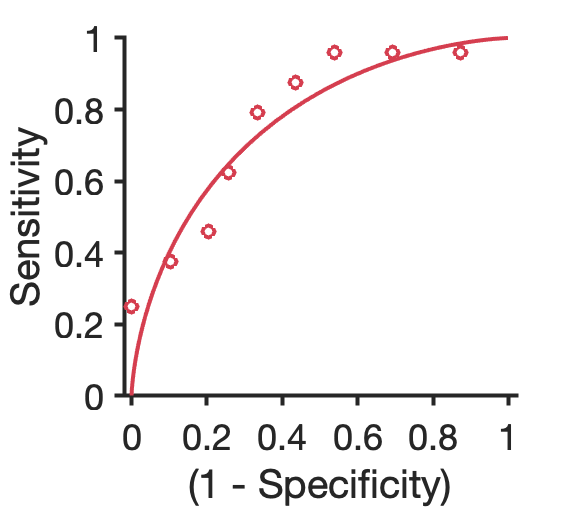

%% Study 5: Classificaton ROC plot, CBP vs. HC, Japan dataset (Fig. 3c)
signature_response1 = cat(2, Study5.ToPS_avg.JP_CBP{:})';
signature_response2 = cat(2, Study5.ToPS_avg.JP_HC{:})';

cols_class = [0.8353    0.2431    0.3098
    0.3765    0.2902    0.4824];

figure;
ROC = roc_plot([signature_response1; signature_response2], [ones(n_subj_JP_CBP,1); zeros(n_subj_JP_HC,1)], 'color', cols_class(1,:), 'nooutput');
set(gca, 'fontsize', 18, 'linewidth', 2, 'ticklength', [.02 .02], 'tickdir', 'out', 'box', 'off');
set(gcf, 'position', [743   518   285   254]);

fprintf('CBP vs. HC, Japan dataset: classification accuracy = %d%%.\n', round(ROC.accuracy*100));

CBP vs. HC, Japan dataset: classification accuracy = 73%.


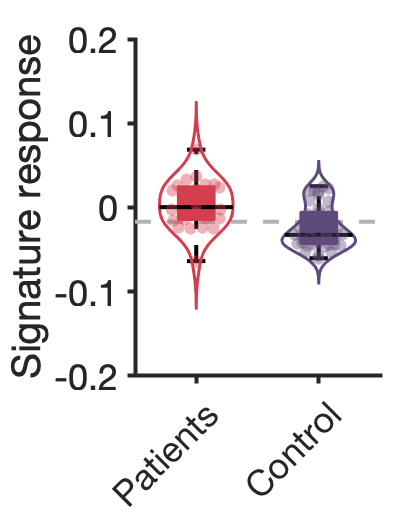

%% Study 5: Classificaton box plot, CBP vs. HC, Japan dataset (Fig. 3c)
figure;
boxplot_wani_2016({signature_response1, signature_response2}, 'color', cols_class, 'refline', ROC.class_threshold, 'linewidth', 2, 'boxlinewidth', 1, 'mediancolor', 'k', 'violin', 'dots');
set(gca, 'fontsize', 18, 'linewidth', 2, 'ylim', [-0.20 0.20]);
set(gcf, 'position', [303   472   210   258])
ylabel('Signature response', 'fontsize', 18); xticklabels({'Patients', 'Control'}); xtickangle(45);

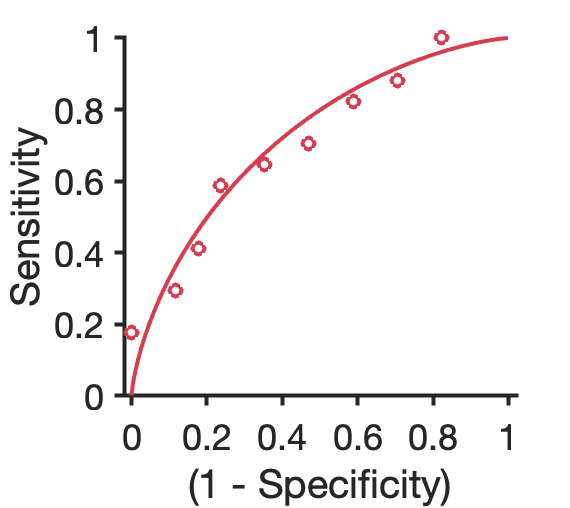

%% Study 5: Classificaton ROC plot, CBP vs. HC, UK dataset (Fig. 3d)
signature_response1 = cat(2, Study5.ToPS_avg.UK_CBP{:})';
signature_response2 = cat(2, Study5.ToPS_avg.UK_HC{:})';

figure;
ROC = roc_plot([signature_response1; signature_response2], [ones(n_subj_UK_CBP,1); zeros(n_subj_UK_HC,1)], 'color', cols_class(1,:), 'nooutput');
set(gca, 'fontsize', 18, 'linewidth', 2, 'ticklength', [.02 .02], 'tickdir', 'out', 'box', 'off');
set(gcf, 'position', [743   518   285   254]);

fprintf('CBP vs. HC, UK dataset: classification accuracy = %d%%.\n', round(ROC.accuracy*100));

CBP vs. HC, UK dataset: classification accuracy = 71%.


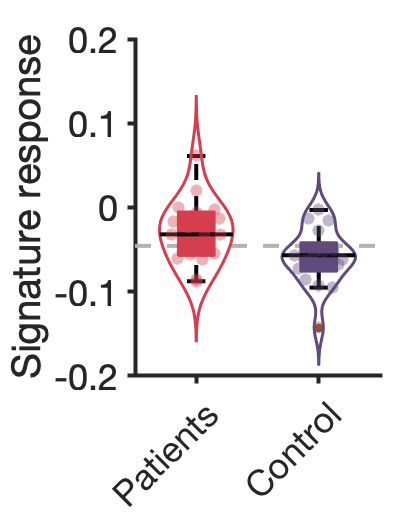

%% Study 5: Classificaton box plot, CBP vs. HC, UK dataset (Fig. 3d)
figure;
boxplot_wani_2016({signature_response1, signature_response2}, 'color', cols_class, 'refline', ROC.class_threshold, 'linewidth', 2, 'boxlinewidth', 1, 'mediancolor', 'k', 'violin', 'dots');
set(gca, 'fontsize', 18, 'linewidth', 2, 'ylim', [-0.20 0.20]);
set(gcf, 'position', [303   472   210   258])
ylabel('Signature response', 'fontsize', 18); xticklabels({'Patients', 'Control'}); xtickangle(45);

### Summary

Great job! We have walked through how to apply ToPS onto multiple fMRI datasets and regenerated main findings of our reference paper (Lee et al., 2020). Here we found that the ToPS is not only sensitive and specific to experimentally-induced sustained pain, but also generalizable to sustained clinical back pain. To promote further validation of the ToPS, we are happy to share our model across different researchers and different laboratories. Thank you for your attention, and please contact us if you have any problem with following this tutorial.

Final edit: 2020. 11. 8

*Jae-Joong Lee* and *Choong-Wan Woo*.